# Event processing. 

This script will combine the behaviour data with the calcium imaging data and combine them into a data structure to continue analysis. 

### **Prerequisits**

- GPIO data from the inscopix recording exported as .csv file

- Events / spikes extracted using Inscopix IDPS software exported as .csv file

- Animal behaviour tracked using the **"**[**1_Behaviour_video_tracking**](matlab:open('./1_Behaviour_video_tracking.mlx'))**" **script. 

### Processing steps

- Import the GPIO data - gets the times of each of the recording sessions in the experiment.

- Import the Event / Spike data -  splits events into the respective recording sessions

- Import the Behaviour data -  gets the tracked data for each recording session.

- Process behaviour/Ca2+ data - combines the behaviour and calcium data and organises into structure

- Process the optogenetic timings - finds the on and off times for the optogenetic stimulation.

- Save the data - save the data for future processing

### Set the name for the analysis

set a unique identifier for the data to be analysed this will be used for the saved output

clear all
analysis_id = 'mu86_day10_squ-optohex2-hex2';

## 1. Process the GPIO files to get start and end timings

- Using the inscopix processing software we can export timings for the recorded data as a .csv file. 

- This .csv file contains the timings of the GPIO ports inluding the one that controls the sync-record LED in the video ("GPIO-1").

- GPIO-1 is high when the calcium frames are being recorded and low when not. 

- From GPIO-1 we can calculate the start and end times for each of the recording sessions.

**Import the GPIO .csv exported from the IDPS. **

this can take a while as its a large data set. Patience mon ami.

[gpio_file GPIO_dir] = uigetfile('*.csv','Select GPIO file');
gpio_data = importdata(fullfile(GPIO_dir,gpio_file));

**Remove the header from the data and then filter the data to get "GPIO-1" data: **

%remove header from text date
gpio_data.textdata(1,:) = [];

GPIOs = string(gpio_data.textdata(:,2));
GPIO_1_time = str2double(gpio_data.textdata(GPIOs == 'GPIO-1'));
GPIO_1_val = gpio_data.data(GPIOs == 'GPIO-1');

**Find the change points in the data where the GPIO switches between high - low:**

gpio_1_val_diff = abs(diff(GPIO_1_val));
change_pts = find(gpio_1_val_diff > 1000);

change_times = GPIO_1_time(change_pts);
start_end_times(:,1) = change_times(1:2:end,:);
start_end_times(:,2) = change_times(2:2:end,:);

**Check each recording session consists of 600 seconds (length of recording session).**

num_sessions = size(start_end_times,1);
diff_check = diff(start_end_times,1,2)

diff_check =   599.9972
  599.9958
  599.9962


## 2. Import the cell event/spike data

- After cell identification in the IDPS we can obtain events or spikes for each of the cells. These can be exported as a .csv file containing the timing of the event and its corresponding cell ID.

- We want to open this .csv file and organise the spikes and events into each of the recording sesisons 

**Open and load the csv file containing the cell event data**

[event_file eventset_dir] = uigetfile(strcat(GPIO_dir,'*.csv'),'Select event data file');
eventset_data = importdata(fullfile(eventset_dir,event_file));
% eventset_data = eventset_data_epoch;
% eventset_data = eventset_data_2;

**Process the csv data into a table with all of the events**

%remove header from text date
eventset_data.textdata(1,:) = [];

%convert the event data into a large table
events_data = cell2table(eventset_data.textdata,"VariableNames",["times" "ids" "amps"]);
events_data.times = str2double(events_data.times);
events_data.ids = string(events_data.ids);
events_data.amps = eventset_data.data;


### Split the spike data into sessions

If there are multiple aligned sessions we can split them into seperate tables. 

%create a new structure to house the session data
session_spikes = struct;

%just in case you didnt run the gpio file 
if ~exist('start_end_times','var')
    start_end_times = [0 max(events_data.times)]   
end

% loop through each session and create a new table containing only events
% from that session
for sesh = 1:num_sessions
    
    %get the start and the end time of the session
    session_str = start_end_times(sesh,1); 
    session_end = start_end_times(sesh,2); 
    
    %split the main events table based on session timings
    session_table = events_data(events_data.times>=session_str & events_data.times<=session_end,:); 
    
    %adjust the timings to make them relative for each session time
    session_table.times = session_table.times - session_str;
    
    %create a field name for the session
    session_id = strcat("session_", string(sesh));
    
    %add the sesssion data to the structure
    session_spikes.(session_id) = session_table; 

end
disp(head(session_spikes.session_1));

    times      ids       amps 
    ______    ______    ______

    8.8933    "C000"    7.4128
    8.9932    "C000"    15.945
    9.0931    "C000"    13.377
    9.1931    "C000"    14.333
     9.293    "C000"    13.476
    9.3929    "C000"    10.888
    14.589    "C000"     8.727
    18.986    "C000"    12.275



*The output is a structure of the different sessions and the spike times and amps for each of the sessions.*

## 3. Import the behavioural data for each session

The next step is to merge the behavour tracking data with the calcium data before we do that we need to get the location of the tracked behaviour data

#### Get the folder where the behavour data is stored 

You can point this to the folder which contains folders for the individual sessions. However the only .mat files should be the behaviour files. *n.b.This won't work if there are additional .mat files.*

behave_dir = uigetdir(GPIO_dir,'Select behaviour data folder');
behave_fold = dir(fullfile(behave_dir, '**', '*tracked_data.mat'));


num_sessions = size(behave_fold,1);
behave_fold.name

ans = 'mu86_day10_240729_s1_tracked_data.mat'

ans = 'mu86_day10_240729_s2_tracked_data.mat'

ans = 'mu86_day10_240729_s3_tracked_data.mat'

Check that the filenames match up to the expected tracked behaviour matlab files.

## 4. Process and combine Calcium data with behaviour data 

Combine the calcium data with the behavour data  

- For each of the calcium events/spikes find the nearest frame time in the behavour tracking 

-  Using the corresponding frame number get event parameters such as the track co-ordinates, left or right traversal and velocity and put into a table. 

session_data = [];
for s = 1:num_sessions

behave_data = importdata(fullfile(behave_fold(s).folder,behave_fold(s).name));

if ~isfield(behave_data.coords,'tracked_norm_coords_cms') %sometimes the havn't saved a default coordinate
    behave_data.coords.tracked_norm_coords_cms = behave_data.coords.norm_red_cordinates_cm;
end


session_id = strcat("session_", string(s));
session_data.(session_id).behave_data = behave_data;

spike_data = session_spikes.(session_id);
frame_time = behave_data.frame_time;

% remove spikes that are not within the behaviour times if video was cut
% short
out_of_time = spike_data.times > max(frame_time);
spike_data(out_of_time,:) = [];


% find the video frame time that has the nearest time to the event to get event frame 
spike_times = spike_data.times;

%find the frame number for behaviour data that 
[h, frame_number] = min(abs(frame_time-spike_times'));
frame_number = frame_number.';

%get the coords, right and left runs for each event. 
event_coords = behave_data.coords.tracked_norm_coords_cms(frame_number,:);
right_runs = ~isnan(behave_data.runs.right_runs(frame_number));
left_runs = ~isnan(behave_data.runs.left_runs(frame_number));

%get the velocity if its not saved?
if ~exist('behave_data.velocity','var')
    distance = abs(diff(behave_data.coords.tracked_norm_coords_cms(1:end,1)));
    velocity = distance./diff(frame_time(1:end,:));
    
    vel_smooth = behave_data.analysis_vars.vel_smooth;
    velocity_smoothed = smooth(velocity,vel_smooth);
    
    velocity_smoothed(end+1) = velocity_smoothed(end);
    session_data.(session_id).behave_data.velocity = velocity_smoothed;
end
event_vel = session_data.(session_id).behave_data.velocity(frame_number,:);


spike_data.x_coord = event_coords(:,1);
spike_data.y_coord = event_coords(:,2);
spike_data.right_run = right_runs;
spike_data.left_run = left_runs;
spike_data.velocity = event_vel;

session_data.(session_id).spike_data = spike_data;

end


#### Organise the data into a cell by cell structure

This way of organising the data seperates each of the cells into a unique structure. This makes it easier to account for cells that have zero events for certain sessions.




all_ids = [];
for s = 1:num_sessions
    session_id = strcat("session_", string(s));
    spike_data = unique(session_data.(session_id).spike_data.ids);
    all_ids = vertcat(all_ids, spike_data);
end
cell_names = unique(all_ids);

    %loop through each session 
for s = 1:num_sessions
    
    cell_data = [];
    session_id = strcat("session_", string(s));

    %loop for all cells
    
    
    spike_data = session_data.(session_id).spike_data;
    %cell_names = unique(events_data.ids); %need to loop through all cells even if they dont ahve spikes   
        for c =  1:size(cell_names,1)
            cell_id = cell_names(c);
            
            %filter for all of the events
            
            events = spike_data(spike_data.ids == cell_id,:);
            cell_data.all_cells.(cell_id) = table2struct(events,"ToScalar",true);
        end
    
        
    %loop filter for events only on right runs
    right_data = spike_data(spike_data.right_run == 1,:);
    right_cells = unique(right_data.ids);
        
        cell_id = [];
        events = [];
        for c =  1:size(right_cells,1)
            cell_id = right_cells(c);
            
            %filter for right events
            events = right_data(right_data.ids == cell_id,:);
            cell_data.right_cells.(cell_id) = table2struct(events,"ToScalar",true);
           
        end
    
    %filter for events only on left runs 
    left_data = spike_data(spike_data.left_run == 1,:);
    left_cells = unique(left_data.ids);
        
        cell_id = [];
        events = [];
        for c =  1:size(left_cells,1)
            cell_id = left_cells(c);
            
            %filter for right events
            events = left_data(left_data.ids == cell_id,:);
            cell_data.left_cells.(cell_id) = table2struct(events,"ToScalar",true);
           
        end
        
    session_data.(session_id).cell_data = cell_data;
    disp(strcat(string(session_id)," has ",string(size(fieldnames(session_data.(session_id).cell_data.all_cells),1))," cells"));...
end

session_1 has 341 cells
session_2 has 341 cells
session_3 has 341 cells


*Check that all three sessions have the same number of cells*

## 5. Process the possible optogenetic stimulation timings - inhibition opto

In some of the sessions optogenetic light stimulation may be delivered during the behaviour. We can get the exact timings of the optogenetics from the GPIO file. we then filter through these to get on and off epochs of the light stimulation and find the corresponding frame number and time in the behviour tracking. 

*n.b. the code uses the true on off times of the OptoLED from the gpio file: OG-LED. The standarf optogentic protocol is continual 20hz stimulation fequency. If this stimulation frequncy or protocol changes then the code may not be reliable. Alternativly the gpio trigger signal could be used to get the optogenetic on/off times. *

No opto stimulation in session 1


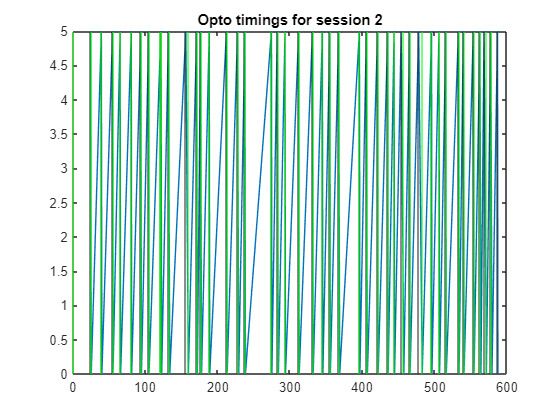

No opto stimulation in session 3


OG_LED_time = str2double(gpio_data.textdata(GPIOs == 'OG-LED'));
OG_LED_val = gpio_data.data(GPIOs == 'OG-LED');
session_fields = fields(session_data);

for s = 1:num_sessions
    seshStart = start_end_times(s,1);
    seshEnd = start_end_times(s,2);
    
    session_index = OG_LED_time > seshStart & OG_LED_time <= seshEnd;
    session_OG_LED_time =  OG_LED_time(session_index);
    session_OG_LED_time = session_OG_LED_time - seshStart;
    
    session_OG_LED_val  =  OG_LED_val(session_index);
    
    first_on = find(session_OG_LED_val>0,1,'first');
    last_on = find(session_OG_LED_val>0,1,'last');
    
    OG_LED_time_real = (session_OG_LED_time(first_on:last_on));
    OG_LED_val_real = (session_OG_LED_val(first_on:last_on));
    
    offtimes = OG_LED_time_real(OG_LED_val_real == 0);
    ontimes = OG_LED_time_real(OG_LED_val_real == 5);
    OG_onoff = [];
    if length(ontimes) > length(offtimes)
        if ontimes(1) ~= 0
            offtimes = [0; offtimes];
        end
    end

    OG_onoff = [ontimes, offtimes];
    
    session_id = string(session_fields(s));
    sessionTimes = session_data.(session_id).behave_data.frame_time;
    
    Behav_OG = zeros(size(sessionTimes));
    OG_onoff_frames = zeros(size(OG_onoff));
    OG_onoff_times = zeros(size(OG_onoff));
    
    for i = 1:size(OG_onoff,1)
        [t ind] = min(abs([sessionTimes sessionTimes] -  OG_onoff(i,:)));
        Behav_OG(ind(1):ind(2)) = 1;
        OG_onoff_times(i,:) = sessionTimes(ind)';
        OG_onoff_frames(i,:) = ind;
    end
    
    
    
    try
        f = figure;
        plot(session_OG_LED_time,session_OG_LED_val)
        hold on 
        xline(OG_onoff(:,1))
        hold on 
        xline(OG_onoff(:,2),'g')
        title(sprintf('Opto timings for session %d',s))
    catch 
        disp(sprintf('No opto stimulation in session %d',s));
        close(f)
    end
    
    
    session_data.(session_id).behave_data.opto.OptoFrames = Behav_OG;
    session_data.(session_id).behave_data.opto.onoff_frames = OG_onoff_frames;
    session_data.(session_id).behave_data.opto.onoff_times = OG_onoff_times;
    session_data.(session_id).behave_data.opto.onoff_inscopix_times = OG_onoff;

end

## 5. Process the possible optogenetic stimulation timings - excitation opto

In some of the sessions optogenetic light stimulation may be delivered during the behaviour. We can get the exact timings of the optogenetics from the GPIO file. we then filter through these to get on and off epochs of the light stimulation and find the corresponding frame number and time in the behviour tracking. 

*n.b. the code uses the true on off times of the OptoLED from the gpio file: OG-LED. The standarf optogentic protocol is continual 20hz stimulation fequency. If this stimulation frequncy or protocol changes then the code may not be reliable. Alternativly the gpio trigger signal could be used to get the optogenetic on/off times. *

OG_LED_time = str2double(gpio_data.textdata(GPIOs == 'OG-LED'));
OG_LED_val = gpio_data.data(GPIOs == 'OG-LED');
session_fields = fields(session_data);
optoStimHz = 20;

for s = 1:num_sessions

    seshStart = start_end_times(s,1);
    seshEnd = start_end_times(s,2);
    
    session_index = OG_LED_time > seshStart & OG_LED_time <= seshEnd;
    session_OG_LED_time =  OG_LED_time(session_index);
    session_OG_LED_time = session_OG_LED_time - seshStart;
    
    session_OG_LED_val  =  OG_LED_val(session_index);
    
    first_on = find(session_OG_LED_val>0,1,'first');
    last_on = find(session_OG_LED_val>0,1,'last');
    
    OG_LED_time_real = (session_OG_LED_time(first_on:last_on));
    OG_LED_val_real = (session_OG_LED_val(first_on:last_on));
    
    changepoints = diff(OG_LED_time_real);
    % need to find the gaps in the opto timings that are greater that the opto stimulation frequency usually 20hz 
    changepoint_ind = find(changepoints>(1/optoStimHz));
    % mode(changepoints) % alternativly if you didnt know the stimulation
    % frequncy you could have the most prevelent changepoint.
    offtimes = OG_LED_time_real(changepoint_ind-1);
    ontimes = OG_LED_time_real(changepoint_ind+1);
    OG_onoff = [];
    OG_onoff(:,1) = [session_OG_LED_time(first_on); ontimes];
    OG_onoff(:,2) = [offtimes; session_OG_LED_time(last_on)];
    
    session_id = string(session_fields(s));
    sessionTimes = session_data.(session_id).behave_data.frame_time;
    
    Behav_OG = zeros(size(sessionTimes));
    OG_onoff_frames = zeros(size(OG_onoff));
    OG_onoff_times = zeros(size(OG_onoff));
    
    for i = 1:size(OG_onoff,1)
        [t ind] = min(abs([sessionTimes sessionTimes] -  OG_onoff(i,:)));
        Behav_OG(ind(1):ind(2)) = 1;
        OG_onoff_times(i,:) = sessionTimes(ind)';
        OG_onoff_frames(i,:) = ind;
    end
    
    
    
    try
        f = figure;
        plot(session_OG_LED_time,session_OG_LED_val)
        hold on 
        xline(OG_onoff(:,1))
        hold on 
        xline(OG_onoff(:,2),'g')
        title(sprintf('Opto timings for session %d',s))
    catch 
        disp(sprintf('No opto stimulation in session %d',s));
        close(f)
    end
    
    
    session_data.(session_id).behave_data.opto.OptoFrames = Behav_OG;
    session_data.(session_id).behave_data.opto.onoff_frames = OG_onoff_frames;
    session_data.(session_id).behave_data.opto.onoff_times = OG_onoff_times;
    session_data.(session_id).behave_data.opto.onoff_inscopix_times = OG_onoff;

end

No opto stimulation in session 1


Array indices must be positive integers or logical values.

## 6. Save the data structure to file

save the data file that contains the behaviour data and the calcium data for each of the sessions

save_path = uigetdir(behave_dir);
session_file = strcat(analysis_id,'_calcium_data.mat')

session_file = 'mu86_day10_squ-optohex2-hex2_calcium_data.mat'

save(strcat(save_path,'\',session_file),'session_data');

## Open up the calcium data file

optional to open up data to add extra data to the data structure


% [session_file session_dir] = uigetfile('*','Select session data file');
% session_data = importdata(fullfile(session_dir,session_file));
% 
% analysis_id = erase(session_file,'_calcium_data.mat');